**Laboratorium 3, 16.03.2023r.**

##  Splot, wprowadzenie do filtrów

Proszę powtórzyć zadanie nr 1 (pomiar tętna), tym razem wykorzystując metodę autokorelacji. Podobnie jak poprzednio, proszę wyznaczyć tętno i określić możliwą do uzyskania rozdzielczość pomiaru (wraz z oceną, od czego ta rozdzielczość zależy). Sygnał wejściowy proszę poddać obróbce wybranymi filtrami wygładzającymi. Podobnie jak poprzednio, proszę przesłać raport w postaci pliku PDF zawierający:

- wykresy sygnału oryginalnego i przefiltrowanego,

- opis wykorzystanych filtrów,

- wyznaczone tętno,

- ocenę rozdzielczości.

Wykonać zadanie metodą obliczania wartości maksymalnych / miejsc zerowych oraz obliczyć odległości między nimi (obliczyć okresy sygnału) i porównać wyniki.

## Definicja parametrów kluczowych

Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)

N = 300;
Fs = 30;
t = 1:1:N; % wektor indeksów ciągu klatek filmu
v = VideoReader('output.mp4'); % import filmu

## Ładowanie obazu do bufora, konwersja

    for i=1:N
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = rgb2gray(read(v,i));
    
        % wyznaczamy średnią z całego obrazu
        sig(i) = mean(I, 'all');
    end

% dla ułatwienia późniejszej analizy odjęcie od sygnału składowej stałej
sig = sig - mean(sig);

## Zastosowanie filtra Gaussowskiego

- używam filtra 15 elementowego ze względu na jego ładne wypłaszczenie wykresu (wykres staje się podobny do funkcji wielomianowej)

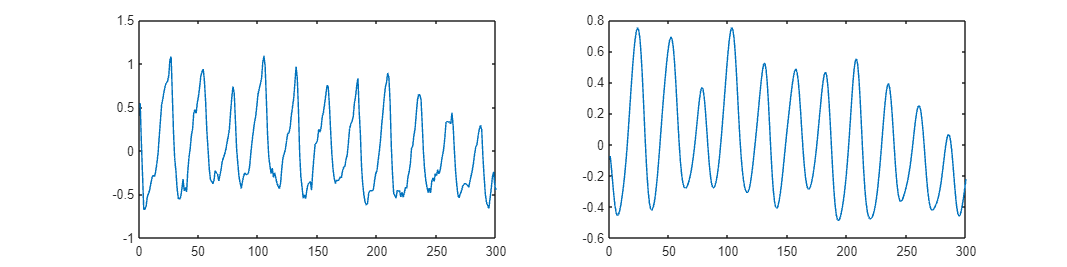

g15 = fspecial('gaussian', [1, 15], 3);
cg15_1 = conv(sig, g15, 'same');

twoplots(t, sig, cg15_1); % wyświetlenie sygnału przed i po filtracji

## Autokorelacja sygnału

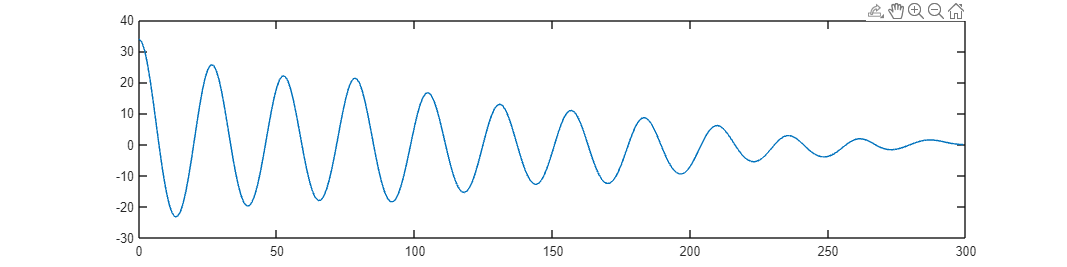

[r, lags] = xcorr(cg15_1);
r = r(lags >= 0);
lags = lags(lags>=0);

clf;
plot(lags, r) % wyświetlenie krzywej autokorelowanego sygnału

## Odczytanie z wykresu okresów pulsu

[~, loc] = findpeaks(r, "MinPeakDistance", 10);
N_peak = 10;    % liczba uwzględnionych okresów
lag_s = (loc(N_peak)-1) / N_peak / Fs;  % uwzględnienie 10 kolejnych peak'ów do wyliczenia dokładniejszej wartości pulsu
ff = 60/lag_s;  % częstotliwość bazowa, bpm liczone w [1/min]
disp("Pomierzone tętno: "); disp(ff)

Pomierzone tętno: 
   68.9655



## Obliczenie pulsu metodą bezpośredniej analizy peak-to-peak 

[~, loc] = findpeaks(cg15_1, "MinPeakDistance", 10); % znalezienie max. lokalnych funkcji z warunkiem oddalenia o 10 indeksów

lag_s = (loc(size(loc,2))-loc(1)) * 1/Fs; % wyznaczenie maksymalnej liczby pełnych okresów peak-to-peak z wykresu f-kcji

ff = 60*(size(loc,2)-1)/lag_s; % udział częstotliwości bazowej, podział zmierzonego czasu na liczbę pełnych okresów
disp("Pomierzone tętno: "); disp(ff)

Pomierzone tętno: 
   68.9655



## Ocena rozdzielczości

- Ze względu na zaszumienie i utratę dokładności związaną z użyciem filtra Gaussowskiego możliwe aberracje wyniku mogą kształtować się na poziomie +- jednego okresu. W związku z tym puls jest podany jako wartość z przedziału <62.0690, 75.8621> BPM

- Rozdzielczość zależy od długości użytego okna czasu poddanego analizie. Analizując 3 okresy uzyskamy mniej dokładny wynik niż analizując ich 30 i uśredniając okres. Na wynik wpływ ma również dokładność filtra - filtr uśredniający gaussa lekko manipuluje wartościami peak'ów zatem zastosowanie zbyt dużego rozmiaru spowoduje zaszumienie maksymów lokalnych.

ff0 = 60*(size(loc,2)-1-1)/lag_s;
ff1 = 60*(size(loc,2)-1+1)/lag_s;
disp([ff0, ff1])

   62.0690   75.8621



## Definicja Funkcji generującej dwa wykresy

Celem jest porównanie filtrowanego sygnału - podfunkcja wykorzystywana w kodzie wyżej.

function twoplots(t, s1, s2)
    figure('Position', [10 10 1200 300]);
    subplot(121);
    plot(t, s1);
    subplot(122);
    plot(t, s2);
end